# Support structure cost - Live script

- Imports sea depth (bathymetry) data

- Sets turbines to random posittions

- Calculates the water depth at each point

- Uses design variables for depths ranges each support type is used in to set support type for each turbine

- Calcuates the cost of support for each turbine 

% importing bathymetry data, setting random turbine coordinates, and
% calculating water depth at each point
[A,R] = readgeoraster('hsb.tif','OutputType','double');
latlim = R.LatitudeLimits;
longlim = R.LongitudeLimits;

info = geotiffinfo('hsb.tif');
height = info.Height; % Integer indicating the height of the image in pixels
width = info.Width; % Integer indicating the width of the image in pixels
x = 1:width;
y = 1:height;

max_lat = 54; 
min_lat = 53.7; 
max_long = 2.8; 
min_long = 2.1;

TCA = zeros([300,4]);%main turbine cost array 

for t=1:300 %for turbine 1 - turbine 300
    
    % set y/longtitude coord 
    TCA(t,2)= min_long + (max_long-min_long).*rand();
    
    % set x/latitide coord
    TCA(t,1)= min_lat + (max_lat-min_lat).*rand();
    
end

TCA

TCA =    53.7585    2.2388         0         0
   53.9641    2.3288         0         0
   53.8212    2.4298         0         0
   53.9907    2.2255         0         0
   53.9533    2.3852         0         0
   53.8130    2.5307         0         0
   53.9355    2.7140         0         0
   53.9442    2.4255         0         0
   53.8288    2.7289         0         0
   53.8790    2.3340         0         0



[rows,cols] = meshgrid(1:height,1:width);
[ADlat,ADlon] = pix2latlon(info.RefMatrix, rows, cols);
Idub=A;
% Interpolate meshgrid of bathymetry data to get water depths at each
% turbine location
TCA(:,3) = interp2(ADlat, ADlon, Idub.', TCA(:,1), TCA(:,2)) % X, Y (not in same order as lat long btw)

TCA =    53.7585    2.2388  -31.5452         0
   53.9641    2.3288  -48.9464         0
   53.8212    2.4298  -34.5858         0
   53.9907    2.2255  -66.0261         0
   53.9533    2.3852  -39.5155         0
   53.8130    2.5307  -31.6160         0
   53.9355    2.7140  -38.0094         0
   53.9442    2.4255  -36.4528         0
   53.8288    2.7289  -46.0666         0
   53.8790    2.3340  -35.4586         0


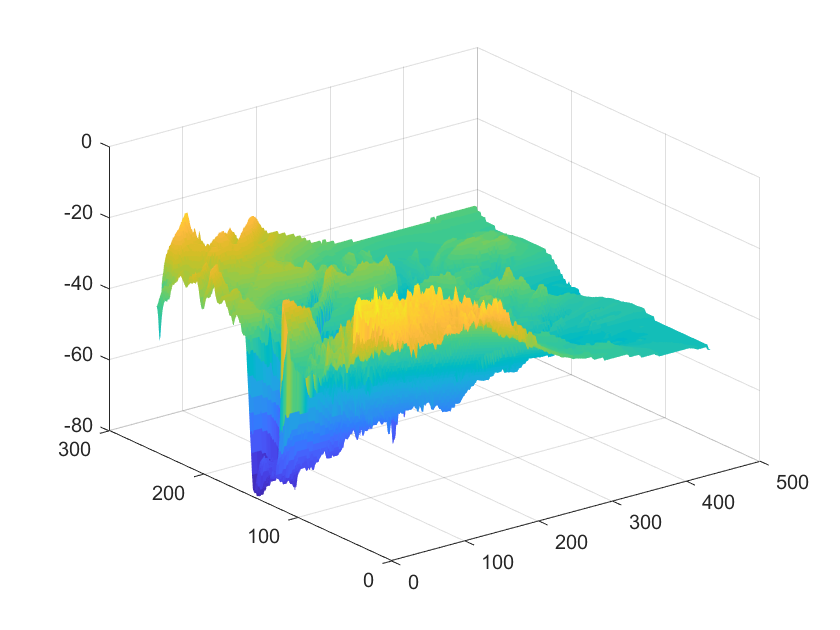

surf(Idub, 'edgecolor', 'none'); colormap(parula(256))

then needs to calculate support structure cost - dependant on water depth 

%"design variables" to optimise each loop = cut off depths for what support
%structure used. no over lap beween depths at which each support type is
%used
mp_limit_var = -30; 
j_limit_var = -80;  %number regarding to sea depth

%split TCA based on depth values, to get seperate arrays of depths for
%different turbine types
mp_tca = TCA(TCA(:,3)>=mp_limit_var,:) 

mp_tca =    53.7933    2.4781  -29.8999         0
   53.7546    2.1499  -28.0457         0
   53.7004    2.5499  -29.0000         0
   53.7382    2.4185  -30.0000         0
   53.9181    2.1061  -29.8568         0
   53.7149    2.1344  -26.9436         0
   53.7661    2.4422  -28.0000         0
   53.8822    2.1165  -30.0000         0
   53.7401    2.2983  -30.0000         0
   53.7109    2.3854  -27.1195         0


j_tca = TCA(TCA(:,3)>=j_limit_var,:) 

j_tca =    53.7585    2.2388  -31.5452         0
   53.9641    2.3288  -48.9464         0
   53.8212    2.4298  -34.5858         0
   53.9907    2.2255  -66.0261         0
   53.9533    2.3852  -39.5155         0
   53.8130    2.5307  -31.6160         0
   53.9355    2.7140  -38.0094         0
   53.9442    2.4255  -36.4528         0
   53.8288    2.7289  -46.0666         0
   53.8790    2.3340  -35.4586         0



%cost of support types - from minimalistic cost model 

gp = 20; %installed generator power in MW
c_t = 1.25*(-0.15+0.92*gp); %cost of wind turbine

%support structure cost equations (for reference, not used in code)
d = 25; %water depth in m
c_mp = (gp*(d*d +100*d +1500))/7500; %monopile
c_j = (gp*(0.5*(d*d)-35*d+2500))/7500; %jacket support structure

mpd = abs(mp_tca(:,3)); %monopile depth
mp_tca(:,4) = (gp*(mpd.^2 +100*mpd +1500))/7500; % cost of monopile support in million euros

%total monopile turbine support costs
tot_mp = sum(mp_tca(:,4),"all");

jd = abs(j_tca(:,3)); %jacket depth
j_tca(:,4) = (gp*(0.5*(jd.^2)-35*jd+2500))/7500 %jacket support structure in million euros

j_tca =    53.7585    2.2388  -31.5452    5.0492
   53.9641    2.3288  -48.9464    5.2927
   53.8212    2.4298  -34.5858    5.0336
   53.9907    2.2255  -66.0261    6.3168
   53.9533    2.3852  -39.5155    5.0605
   53.8130    2.5307  -31.6160    5.0486
   53.9355    2.7140  -38.0094    5.0454
   53.9442    2.4255  -36.4528    5.0361
   53.8288    2.7289  -46.0666    5.1966
   53.8790    2.3340  -35.4586    5.0336



% total jacket turbine support cost
tot_j = sum(j_tca(:,4),"all");


%  Total support structure cost (in million euros)
tot_support_cost = tot_mp + tot_j

tot_support_cost = 2.2691e+03